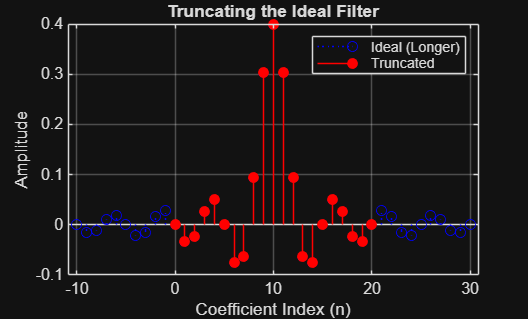

% Filter Specifications
order = 20;
cutoff_norm = 0.2; 
M = order / 2;

% --- Step 2b: Making it Practical (Explicit Truncation) ---

% 1. Calculate the ideal filter over a WIDER range (e.g., from -10 to 30)
wider_indices = -10:30;
x_wide = 2 * cutoff_norm * (wider_indices - M);
h_ideal_long = sin(pi * x_wide) ./ (pi * x_wide);
h_ideal_long(wider_indices == M) = 1; % Handle sinc(0)=1
h_ideal_long = h_ideal_long * (2 * cutoff_norm);

% 2. Now, TRUNCATE by selecting only the coefficients from n=0 to n=20.
% In our 'wider_indices' array, n=0 is the 11th element and n=20 is the 31st.
h_truncated = h_ideal_long(11:31);

% --- Let's visualize the "cut" ---
figure;
stem(wider_indices, h_ideal_long, 'b:'); % Dotted blue for the long version
hold on;
stem(0:order, h_truncated, 'r', 'filled'); % Solid red for our truncated version
title('Truncating the Ideal Filter');
xlabel('Coefficient Index (n)');
ylabel('Amplitude');
legend('Ideal (Longer)', 'Truncated');
grid on;

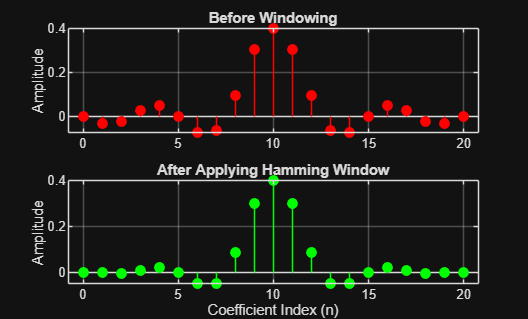


% --- Step 2c: Smooth the Edges with a Window ---

% First, create the 21 points of the Hamming window
N = order;
n_indices = 0:N;
hamming_window = 0.54 - 0.46 * cos(2 * pi * n_indices / N);

% Now, apply the window. We multiply our truncated filter by this window
% element by element. In MATLAB, this is done with '.*'
h_final = h_truncated .* hamming_window;

% --- Let's visualize the result ---
figure;
subplot(2,1,1);
stem(0:N, h_truncated, 'r', 'filled');
title('Before Windowing');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
stem(0:N, h_final, 'g', 'filled');
title('After Applying Hamming Window');
xlabel('Coefficient Index (n)');
ylabel('Amplitude');
grid on;